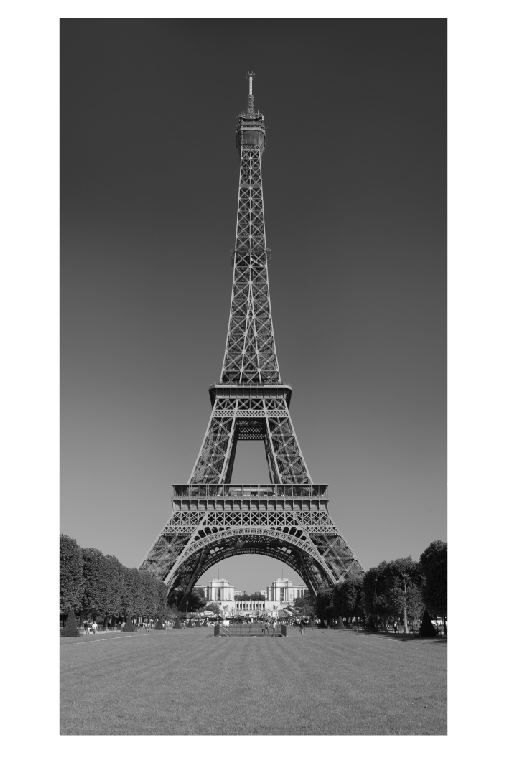

% setup
img_c = imread("eiffelturm1.jpg");
img = im2gray(img_c);
figure;
imshow(img);

% harris
figure;
harris = detectHarrisFeatures(img);
harris 

harris =   1375×1 cornerPoints array with properties:

    Location: [1375×2 single]
      Metric: [1375×1 single]
       Count: 1375


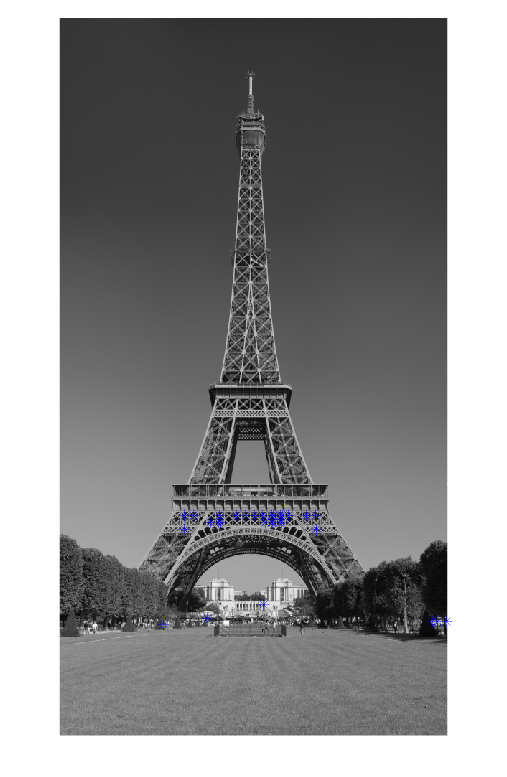

imshow(img);hold on;
strongest_h = harris.selectStrongest(30);
plot(strongest_h.Location(:,1), strongest_h.Location(:,2), 'b*', MarkerSize=10);

% shi
shi = detectMinEigenFeatures(img);
shi

shi =   2914×1 cornerPoints array with properties:

    Location: [2914×2 single]
      Metric: [2914×1 single]
       Count: 2914


sprintf("There ahve been found %d feautures", shi.Count)

ans = "There ahve been found 2914 feautures"

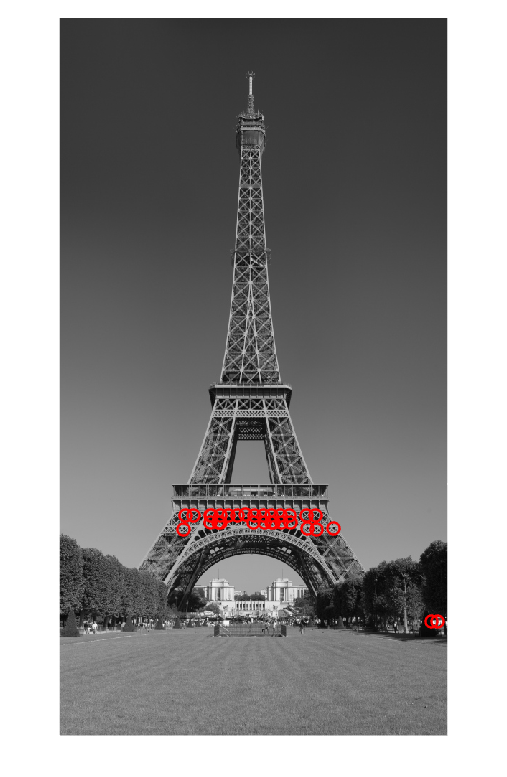

figure;
imshow(img);hold on;
strongest_s = shi.selectStrongest(30);
plot(strongest_s.Location(:,1), strongest_s.Location(:,2), 'ro', MarkerSize=10, LineWidth=2);

% surf
surf = detectSURFFeatures(img);
surf

surf =   742×1 SURFPoints array with properties:

              Scale: [742×1 single]
    SignOfLaplacian: [742×1 int8]
        Orientation: [742×1 single]
           Location: [742×2 single]
             Metric: [742×1 single]
              Count: 742


sprintf("There ahve been found %d feautures", surf.Count)

ans = "There ahve been found 742 feautures"

figure;
imshow(img);hold on;
strongest_surf = surf.selectStrongest(30);
[features, points] = extractFeatures(img, strongest_surf);
strongest_surf.Orientation = points.Orientation;
mean(points.Orientation)

ans = single
2.6320

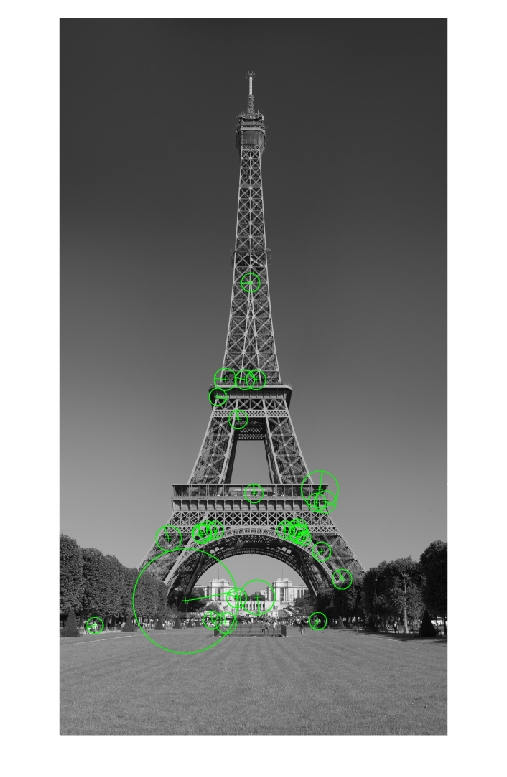

strongest_surf.plot(ShowOrientation=true)

Die Orientierung ist tatsöchlich nicht sonderlich eindeutig da sie von Punkt zu Punkt unterschiedlich ist. Ich würde sagen die meisten Orientierungen sind richtung oben/links. Auch das Mean der Orientierungen geht nach oben links.